% señales x[n] e y[n]
x = [1, 2, 8, 15, 3, 2, 8, 16, 24, 8, 3];
y = [15, 2, 5, 3, 3, 8, 2, 1, 4, 2, 7];

% suma de las señales
suma = x + y;

% multiplicación de las señales
multiplicacion = x .* y;

% vector de índices n para la representación tabular
n = 0:length(x) - 1;

tabla = table(n', x', y', suma', multiplicacion', 'VariableNames', {'n', 'x[n]', 'y[n]', 'x[n]+y[n]', 'x[n]*y[n]'});
disp(tabla);

    n     x[n]    y[n]    x[n]+y[n]    x[n]*y[n]
    __    ____    ____    _________    _________

     0      1      15        16           15    
     1      2       2         4            4    
     2      8       5        13           40    
     3     15       3        18           45    
     4      3       3         6            9    
     5      2       8        10           16    
     6      8       2        10           16    
     7     16       1        17           16    
     8     24       4        28           96    
     9      8       2        10           16    
    10      3       7        10           21    



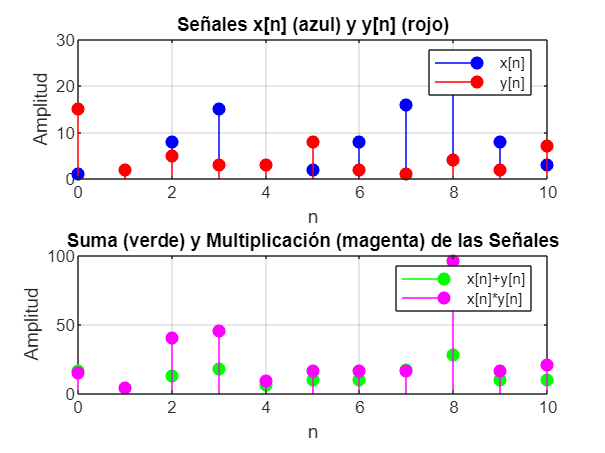


subplot(2, 1, 1);
stem(n, x, 'b', 'filled');
hold on;
stem(n, y, 'r', 'filled');
title('Señales x[n] (azul) y y[n] (rojo)');
legend('x[n]', 'y[n]');
xlabel('n');
ylabel('Amplitud');
grid on;

subplot(2, 1, 2);
stem(n, suma, 'g', 'filled');
hold on;
stem(n, multiplicacion, 'm', 'filled');
title('Suma (verde) y Multiplicación (magenta) de las Señales');
legend('x[n]+y[n]', 'x[n]*y[n]');
xlabel('n');
ylabel('Amplitud');
grid on;